clc
clear
load v_k.mat
k=1;

ydata=v_k(:,k);
x=200:200:800;
new_x=100:200:900;
p=pchip(x,ydata,new_x);%插值
y=zeros(1,9);
for j=1:9
   if mod(j,2)==0
       y(j)=ydata(j/2);
   else
       y(j)=p((j+1)/2);
   end
end

[vmax, maxx] = max(y);
maxx=maxx*100;%maxx最大生长速率对应的降水量(索引是4，则对应的降水量为4)
a0=[0.00001 0.01 0.1 1 1]; % a 初始值
x=100:100:900;

for i=1:80

    fun=@(a,x) a(3)*vmax./(1+a(1).*exp(a(2).*(x-maxx-a(5))))+a(3)*vmax./(1+a(1).*exp(-a(2).*(x-1.5*maxx-a(5))))-1.5.*vmax(1)+a(4);

    [a,resnorm]=lsqcurvefit(fun,a0,x,y,[0,0,0,0],[5,0.5,500,500]);

    a0=a;

end


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr

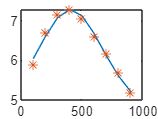



plot(x,fun(a,x),x,y,'*');


temp=a(5);
a(5)=a(3);
a(3)=0.5*maxx;
a(4)=-(a(5)-maxx);
a(6)=resnorm;